# AdEx simulation

## List simulation parameters

% Neuron parameters

     params.C = 200; % capacitance
    params.gl = 10; % leak conductance
    params.El = -58; % leak voltage
    params.vt = -50; % resting membrane potential
  params.delT = 2; % spike width
     params.a = 2; % resonantor/integrator constant
  params.tauW = 120; % adaptation decay time
     params.b = 100; % adaptation jump (for updating w)
params.vreset = -46; % voltage reset value


% Simulation time parameters
params.simDur = 500; % simulation time in ms
    params.dt = 0.01; % integration time step in ms
    
    
% input current
 params.input = 500; % input current in pA


## Run the simulation

 memvolt = simulateAdEx(params);

## Plot the result

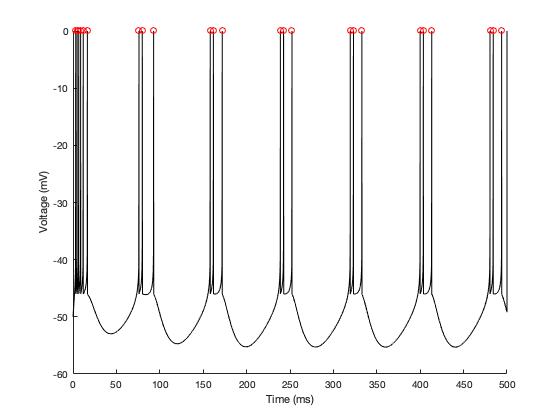

timevec = (0:length(memvolt)-1)*params.dt;


% find the APs
[~,spikelocs] = findpeaks(memvolt);


% plot the membrane potential and APs on top
figure, hold on
plot(timevec,memvolt,'k')
plot(timevec(spikelocs),memvolt(spikelocs),'ro')

xlabel('Time (ms)')
ylabel('Voltage (mV)')

 print('membrane_potential.png','-dpng')
 print('membrane_potential.pdf','-dpdf')

## Run the simulation for various input strengths

% range of inputs
inputs = linspace(10,600,20);

% initialize outputs (sps = spikes per second)
sps = zeros(size(inputs));

% loop over input strengths and run experiment
for ini=1:length(inputs)
    
    % update parameters structure and run simulation
    params.inputs = inputs(ini);
     memvolt = simulateAdEx(params);
    % find peaks
    [~,spikelocs] = findpeaks(memvolt,'MinPeakHeight',-20);
    
    % convert to sikes per second
    sps(ini) = numel(spikelocs) / (params.simDur/1000);
end

## Plot the FI curve

figure
plot(input(eps,'ko-','markerfacecolor','w','linew',2,'markersize',10))

Error using input
Too many input arguments.

xlabel('Input (pA)')
ylabel('Spike count (spikes per second)')
title('F/I curve')